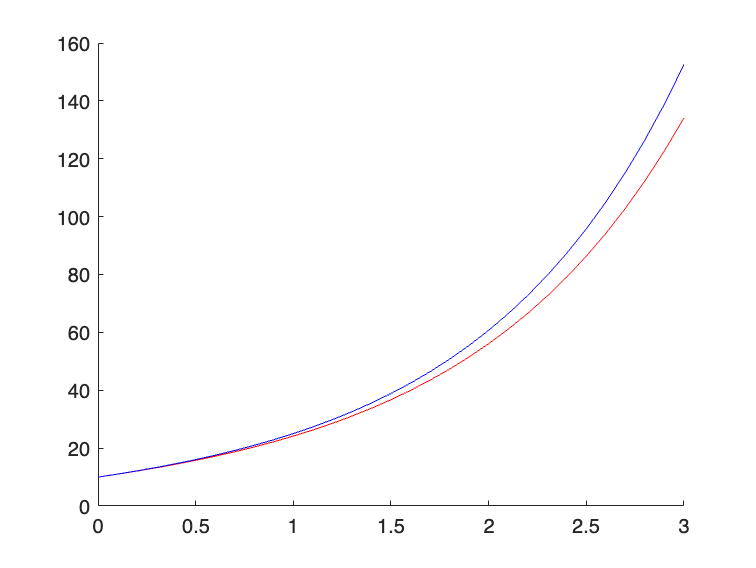

f = @(x, y) y - 3*x;
g = @(x) 7*exp(x) + 3*x + 3;

y0 = 10;
x0 = 0;
xn = 3;

dx = 0.1;

x = x0 : dx : xn;
y = zeros(size(x));
y_exact = g(x);
m = zeros(size(x));

y(1) = y0;
 
for i = 1:length(x) - 1
    y(i + 1) = y(i) + dx*(f(x(i), y(i)));
end

figure;
hold on;
plot(x, y, 'r');
plot(x, y_exact, 'b');
hold off;